data = xlsread('WDMStoppingData.xlsx', 'Downshift Data')

data =   532.0000       NaN    1.8580       NaN   12.0000  101.0539         0   14.8220    0.0630   14.8890    0.0640   14.8270    0.0630   14.8360    0.0640   11.9880    0.0750    2.8550    0.0820
  532.0000       NaN    1.8580       NaN   12.0000  101.0539         0   14.8880    0.0630   14.9040    0.0630   14.8690    0.0650   14.9260    0.0630   11.8480    0.0800    3.0490    0.0860
  532.0000       NaN    1.8580       NaN   12.0000  101.0539         0   14.8690    0.0650   14.9210    0.0630   14.8310    0.0640   14.8810    0.0620   12.0180    0.0860    2.8570    0.0920
  553.0000       NaN    2.4280       NaN   12.0000  137.2680         0   14.8430    0.0630   14.9250    0.0630   14.9050    0.0970   14.9090    0.0650   11.0090    0.0790    3.8840    0.0860
  468.0000    4.9743    2.3248    0.0102   12.0000  111.2313    1.2782   14.8280   14.5670   14.6140   14.6240    0.0630    0.0620    0.0630    0.0630   11.4400    0.0770    3.2180    0.0840
  437.8000    6.0968    2.3248    0.01

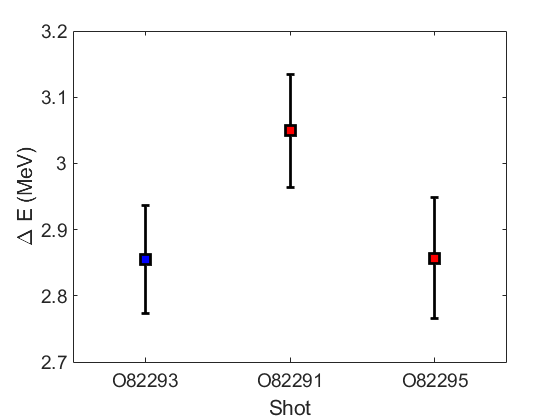


rhoR = data(:,6:7);
downshift = data(:, 18:19);

beCold = 1;
beWarm = 2:3;

bCold = 4:6;
bWarm = 7:11;

figure; hold on; box on; 
xlim([0.5 3.5])
xlabel('Shot')
ylabel(['\Delta E (MeV)'])
set(gca, 'FontSize', 14)

errorbar(beCold, downshift(beCold,1), downshift(beCold,2), ...
    "LineStyle", 'none', ...
    'Marker', 'square', ...
    'Color', 'k', ...
    'MarkerFaceColor', 'b', ...
    'LineWidth', 2, ...
    "MarkerSize", 10)

errorbar(beWarm, downshift(beWarm,1), downshift(beWarm,2), ...
    "LineStyle", 'none', ...
    'Marker', 'square', ...
    'Color', 'k', ...
    'MarkerFaceColor', 'r', ...
    'LineWidth', 2, ...
    "MarkerSize", 10)

set(gca, 'XTick', 1:3)
set(gca, 'XtickLabel', {'O82293', 'O82291', 'O82295'})

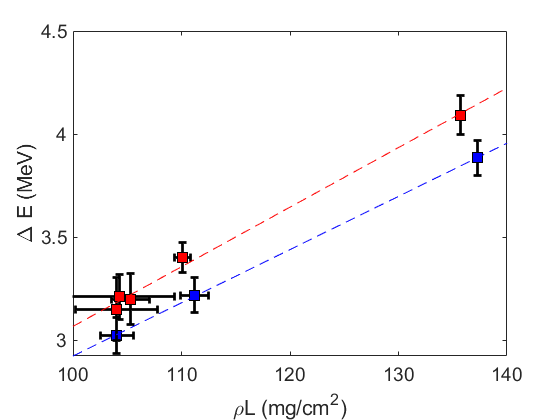






figure; hold on; box on;
xlabel('\rhoL (mg/cm^2)')
ylabel('\Delta E (MeV)')
set(gca, 'FontSize', 14)
xlim([100 140])

errorbar(rhoR(bCold, 1), downshift(bCold, 1), downshift(bCold, 2), downshift(bCold, 2), rhoR(bCold, 2), rhoR(bCold, 2), ...
     "LineStyle", 'none', ...
    'Color', 'k', ...
    'LineWidth', 2, ...
    "MarkerSize", 10)

scatter(rhoR(bCold, 1), downshift(bCold, 1), 'square', 'MarkerFaceColor', 'b', 'MarkerEdgeColor','k', 'SizeData', 100)

errorbar(rhoR(bWarm, 1), downshift(bWarm, 1), downshift(bWarm, 2), downshift(bWarm, 2), rhoR(bWarm, 2), rhoR(bWarm, 2), ...
     "LineStyle", 'none', ...
    'Color', 'k', ...
    'LineWidth', 2, ...
    "MarkerSize", 10)

scatter(rhoR(bWarm, 1), downshift(bWarm, 1), 'square', 'MarkerFaceColor', 'r', 'MarkerEdgeColor','k', 'SizeData', 100)

f = fit(rhoR(bCold, 1), downshift(bCold, 1), 'poly1');
plot([95 140], f([95, 140]), '--b')

f = fit(rhoR(bWarm, 1), downshift(bWarm, 1), 'poly1');
plot([95 140], f([95, 140]), '--r')